# **ACM 11 Homework 4 Part 1/3 (Spring 2024)**

## **Due Friday, May 24, 11:59pm Pacific Time, by upload to Canvas.**

This assignment consists of three parts. This part is worth $40$ points. You should read the problem set-up in this file and follow the instructions to write and test your code. 

This part is independent of Part 2 and Part 3, you can do them in any order. When you are done with both parts, zip all of your files needed to run the code into a single zip and upload to Canvas.

## **Motivation**

It is of vital importance in the scientific or engineering practice to evaluate integrals like $\int_\Omega f(x)dx$, where $f$ is some function that doesn't necessarily have an analytical form but only supports evaluation, and the region $\Omega \subset {\mathbf{R}}^d$. 

Even if sometimes people are lucky enough to meet an analytical $f$, we could still have no access to a closed-form formula for the integral (for example, try finding a combination of elementary functions that evaluates $\int_{-\infty}^y e^{-x^2} dx$). 

The numerical solution to such integral $\int_\Omega f(x)dx$ consists of two approaches: a deterministic one named numerical quadrature, and a stochastic one called the Monte Carlo method. 

To start with, we clean our Workspace in `MATLAB` to avoid confusion.

clear

### Problem 1: Numerical Quadrature (20 points)

Numerical quadrature is a very classic method that estimates the integral $\int_\Omega f(x)dx$ by a weighted sum: 


$$\int_\Omega f(x)dx \approx \sum_{i=1}^{n}w_i f(x_i)$$


The weights $w_i$ and the abscissa $x_i$ are carefully chosen so that the estimate is accurate for a large class of simple functions $f$, such as polynomials. ("Abscissa" is a fancy way to refer to the horizontal coordinate of a graph, and is common in quadrature literature.)

**Problem 1a (5 points): **Define our target functions:

 
$$f\left(x\right)=e^{x-x^2 \;\sin \left(2x\right)}$$


 
$$g\left(x,y\right)=e^{x^2 +y-\tanh \left(2y\right)}$$


Replace the 0 in the code block below with the appropriate function.

f = @(x) exp(x - (x.^2).*sin(2.*x));     
g = @(x,y) exp((x.^2) + y - tanh(2.*y));   

**Problem 1b (5 points): **Let the region $\Omega ={\left\lbrack 0,1\right\rbrack }^d$. For dimension $d=1,2$, complete the skeleton code for the Gaussian quadrature rule in the file `GQ.m`. Here $n$ is the number of abscissas we would have along one dimension. In other words, there are $n^d$ abscissas in total. See the notes/class slides on multivariate integrals for the appropriate formula for approximating a 2D integral.

**Problem 1c (5 points): **For $n=2,3,4,5,6,7,8$, compare the output of the `GQ` function with the output of the built-in functions `integral` and `integral2` (for $d=1,2$respectively). The output of the latter functions will serve as the reference value for the true integral. You should measure the error of `GQ` with respect to the reference integral value by absolute value, and plot it against the number of total abscissas used (be careful, it should be $n^d$). Put the error plot for $f$ and $g$ in one single figure, mark their data points with different styles and colors, and use the log scale for $x$- and $y$-axes. Include appropriate axes labels and a legend. You may find the function `loglog `helpful.

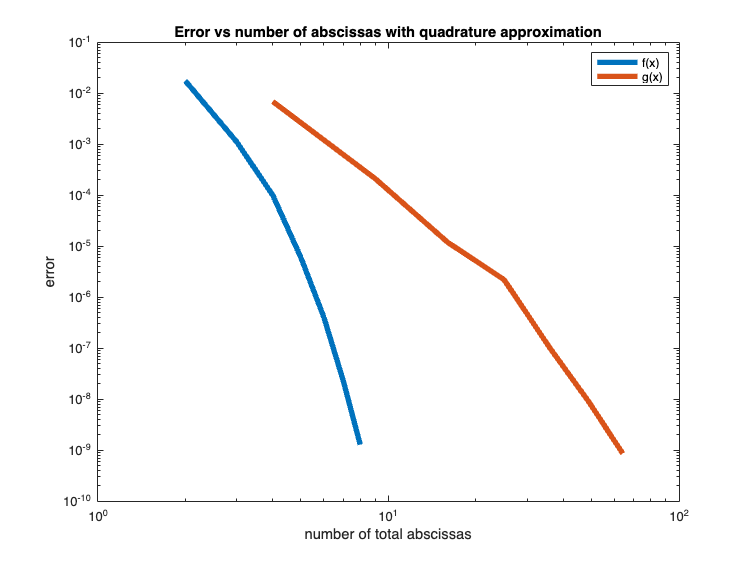

n = [2, 3, 4, 5, 6, 7, 8];
exact1 = integral(f,0,1);
exact2 = integral2(g,0,1,0,1);
err = zeros(length(n),2);
n_plot = zeros(length(n));
for i = 1:length(n)
    estimate1 = GQ(f, 1, n(i));
    err(i,1) = abs(exact1 - estimate1);

    estimate2 = GQ(g, 2, n(i));
    err(i, 2) = abs(exact2 - estimate2);
    n_plot(i) = n(i)^2;
end

loglog(n, err(:, 1)', 'LineWidth', 4);
hold on;
loglog(n_plot, err(:, 2)', 'LineWidth', 4);

legend('f(x)', 'g(x)');
xlabel('number of total abscissas');
ylabel('error');
title('Error vs number of abscissas with quadrature approximation');
hold off;

**Problem 1d (5 points): **How does the convergence of the quadrature estimate the integral (slope of the error) differ between these two functions? Explain your observation in terms of the integral dimension $d$.

fprintf(['For a higher integral dimension, the quadrature estimate is slightly worse\n' ...
    'than the lower integral dimension because the slope of the error is slightly larger in magnitude for d = 1, \n' ...
    'than for d = 2. The slopes for both error plots are negative, which means that a larger number of total abscissas \n' ...
    'decreases the error. '])

For a higher integral dimension, the quadrature estimate is slightly worse
than the lower integral dimension because the slope of the error is slightly larger in magnitude for d = 1, 
than for d = 2. The slopes for both error plots are negative, which means that a larger number of total abscissas 
decreases the error. 

### Problem 2: Monte Carlo Estimate (20 points)

Another approach to estimate the integral $\int_\Omega f(x)dx$ is to write it in the expectation form: 


$$\int_\Omega f(x)dx = |\Omega| \cdot {\mathbb E}_{u\sim U(\Omega)}[f(u)]$$


where $|\Omega |$ is the length/area/volume of the region $\Omega$, and $u$ is a random variable that is uniformly distributed on $\Omega$. Then, we can use the Monte Carlo method to estimate this expectation. Let $u_1 ,\ldotp \ldotp \ldotp ,u_n$ be the i.i.d. samples from the uniform distribution on $\Omega$, then 


$${\mathbb E}_{u\sim U(\Omega)}[f(u)]\approx \frac{1}{n} \sum_{i=1}^{n}f(u_i)$$


Thus we conclude that


$$\int_\Omega f(x) dx \approx \frac{|\Omega|}{n} \sum_{i=1}^{n} f(u_i)$$


**Problem 2a (5 points): Complete the function at the bottom of this file named** `MCE` that takes in the function $f$, dimension $d$, and number of samples $n$, and outputs the Monte Carlo estimate. Here we assume that $\Omega ={\left\lbrack 0,1\right\rbrack }^d$. You may use `rand` to generate a random variable uniformly distributed between 0 and 1.

**Problem 2b (10 points): **For $n=10,100,1000,10000$, compare the output of the `MCE` function with the built-in functions `integral` and `integral2` (for $d=1,2$ respectively). Due to the randomness, for each $n$, we want you to call `MCE` for $100$ times, and use the mean of their absolute difference with respect to the reference integral value as the error. You may find the function `mean` helpful. Plot the error against the number of total samples used. Put the error plot for $f$ and $g$ in one single figure, mark their data points with different styles and colors, and use the log scale for both $x$- and $y$-axes. You may find the function `loglog `helpful.

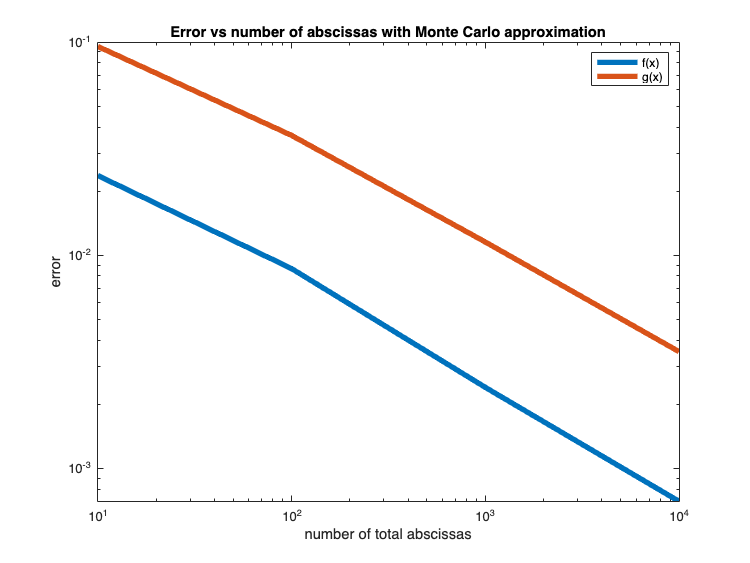

n = [10, 100, 1000, 10000];
exact1 = integral(f,0,1);
exact2 = integral2(g,0,1,0,1);
err1 = zeros(1, length(n));
err2 = zeros(1,length(n));
for i = 1:length(n)
    for j = 1:100
        err1(i) = err1(i) + abs(exact1 - MCE(f, 1, n(i)));
        err2(i) = err2(i) + abs(exact2 - MCE(g, 2, n(i)));
    end
    err1(i) = err1(i) / 100;  
    err2(i) = err2(i) / 100; 
end

loglog(n, err1', 'LineWidth', 4);
hold on;
loglog(n, err2', 'LineWidth', 4);

legend('f(x)', 'g(x)');
xlabel('number of total abscissas');
ylabel('error');
title('Error vs number of abscissas with Monte Carlo approximation');
hold off;

**Problem 2c (5 points): **How does the convergence of the Monte Carlo estimate of the integral (slope of the error) behave for these two functions? How is this different from the convergence behavior of the traditional quadrature approach? Is this theoretically expected?

fprintf(['The slope of the error for the Monte Carlo estimate is linear and negative for both dimensions. \n' ...
    'However, the plot for d = 2 is shifted up from the plot for d = 1, meaning that the error is larger for \n' ...
    'all numbers of abscissas for d = 2 than d = 1.'])

The slope of the error for the Monte Carlo estimate is linear and negative for both dimensions. 
However, the plot for d = 2 is shifted up from the plot for d = 1, meaning that the error is larger for 
all numbers of abscissas for d = 2 than d = 1.

## Problem 3: Time Spent (0 points)

How many hours did you spend on this homework, part 1? Please round to the nearest half hour. 

hours = 2;

Here is the MCE function referenced above.

function I = MCE(func,d,n)
assert(d==1|d==2,"Invalid dimension")

if d==1
    random = rand(1, n);
    
    I = sum(func(random)) / n;
else
    random1 = rand(1, n);
    random2 = rand(1, n);
    I = sum(func(random1, random2)) / n;
end
end
